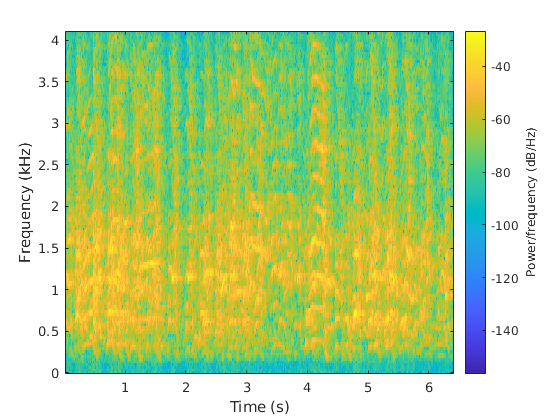

% Task 4
load laughter;

soundsc(y);
spectrogram(y, 256, [], [], Fs, 'yaxis');

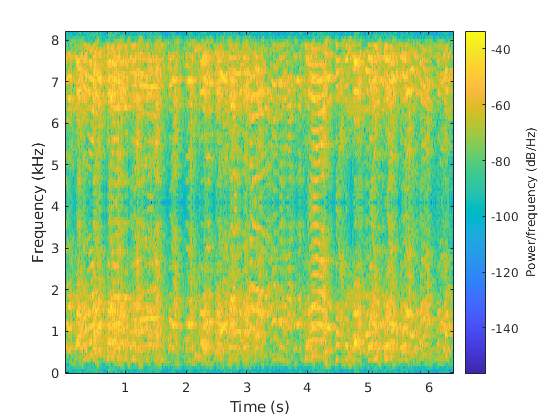

pause(8);

L = 2;
Fs2 = Fs*2;

z=zeros(2*length(y),1);
z(1:2:end)=y;

soundsc(z,Fs2);
spectrogram(z, 256, [], [], Fs2, 'yaxis');

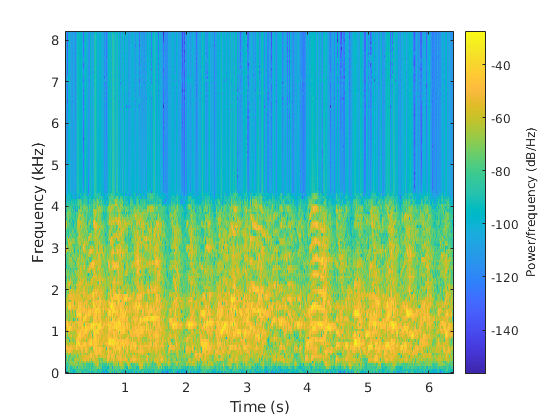

pause(8);

N = 100+1;
deltaf = 3.3/N;
fp=((1/(2*L))-deltaf)/Fs2;
fs=(1/(2*L))/Fs2;
fc = (fp+fs)/2;
%[b,a] = fir1(100,2*fc);
[b,a] = fir1(100,1/2);

result1=L*filter(b,a,z);
soundsc(result1,Fs*L);
spectrogram(result1, 256, [], [], Fs*L, 'yaxis');

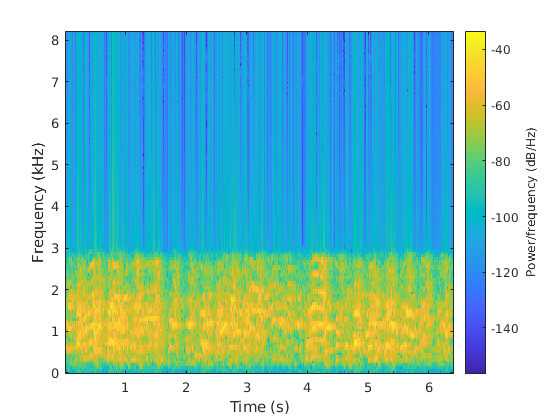

% Task 5

M= 3;
% antialiasing filter design
fp=((1/(2*M))-deltaf)/Fs2;
fs=(1/(2*M))/Fs2;
fc = (fp+fs)/2;
%[b,a] = fir1(100,2*fc);
[b,a] = fir1(100,1/3);

result2 = filter(b,a,z);
spectrogram(result2,256, [], [], Fs2, 'yaxis');

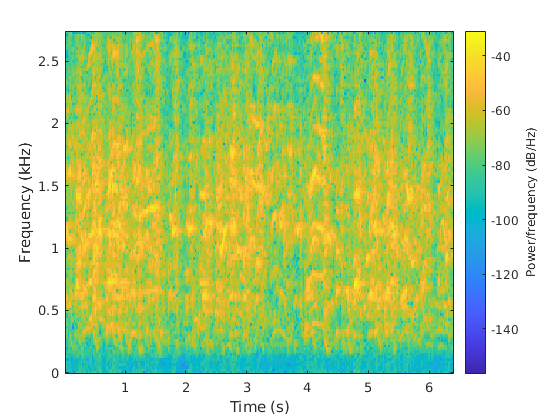

soundsc(result2,Fs*2);

pause(8);
result3=result2(1:3:end);
spectrogram(result3,256, [], [], Fs*(2/3), 'yaxis');

soundsc(result3,Fs*(2/3));